# Robotics I - 

#  - 2019

## Exercise 1

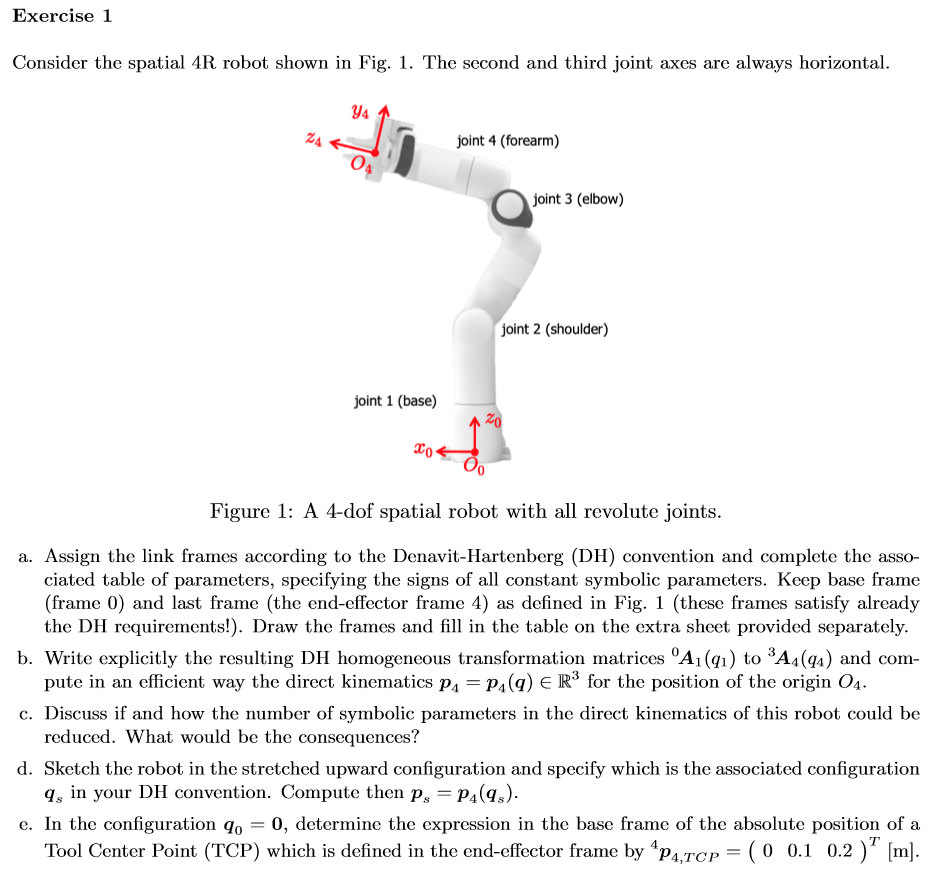

clear
sigma = [0,0,0,0]

sigma =      0     0     0     0


n = length(sigma)

n = 4

q = sym('q', [n,1]);
a = sym('a', [n,1]);
d = sym('d', [n,1]);

dhTable = [-pi/2 , 0 , d(1) q(1);
            0 , a(2) , 0 , q(2);
            -pi/2 , a(3) , 0 , q(3) ; 
            0 , 0 , d(4) , q(4)]

$$dhTable = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & d_{1} & q_{1}\\ 0 & a_{2} & 0 & q_{2}\\ -\frac{\pi }{2} & a_{3} & 0 & q_{3}\\ 0 & 0 & d_{4} & q_{4} \end{array}\right)$$


[T_Total, T_Partial] = getTransformationMatrix(dhTable, 'alpha')

$$T\_Total = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\sigma_{2} & \cos\left(q_{4}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{4}\right)\,\sigma_{2} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{3}\\ -\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sigma_{1} & \sin\left(q_{4}\right)\,\sigma_{1}-\cos\left(q_{1}\right)\,\cos\left(q_{4}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{3}\\ -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right) & -\cos\left(q_{2}+q_{3}\right) & d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$

T_Partial = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}



p = T_Total(1:3,4) % Position of end effector;

$$p = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)\\ d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

## Exercise 2

[Jl Ja] = getJacobian(dhTable, sigma, 'alpha')

$$Jl = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(q_{1}\right)\,\sigma_{3} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & 0\\ \cos\left(q_{1}\right)\,\sigma_{3} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & 0\\ 0 & \sigma_{4}-\sigma_{5}-a_{2}\,\cos\left(q_{2}\right) & \sigma_{4}-\sigma_{5} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{4}\,\cos\left(q_{2}+q_{3}\right)+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=d_{4}\,\cos\left(q_{2}+q_{3}\right)+a_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{3}=\sigma_{5}-\sigma_{4}+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{4}=d_{4}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{5}=a_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

$$Ja = \left(\begin{array}{cccc} 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 1 & 0 & 0 & -\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$


sincos_ = getShortNotation_SinCos(n);
Jl_ = toShortNotation(Jl,sincos_)

$$Jl\_ = \begin{array}{l} \left(\begin{array}{cccc} -s_{1}\,\sigma_{2} & -c_{1}\,\sigma_{1} & -c_{1}\,\left(c_{2,3}\,d_{4}+a_{3}\,s_{2,3}\right) & 0\\ c_{1}\,\sigma_{2} & -s_{1}\,\sigma_{1} & -s_{1}\,\left(c_{2,3}\,d_{4}+a_{3}\,s_{2,3}\right) & 0\\ 0 & d_{4}\,s_{2,3}-a_{3}\,c_{2,3}-a_{2}\,c_{2} & d_{4}\,s_{2,3}-a_{3}\,c_{2,3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2,3}\,d_{4}+a_{2}\,s_{2}+a_{3}\,s_{2,3}\\ \sigma_{2}=a_{2}\,c_{2}+a_{3}\,c_{2,3}-d_{4}\,s_{2,3} \end{array}$$

T_total_ = toShortNotation(T_Total, sincos_)

$$T\_total\_ = \begin{array}{l} \left(\begin{array}{cccc} s_{1}\,s_{4}+c_{4}\,\sigma_{2} & c_{4}\,s_{1}-s_{4}\,\sigma_{2} & -c_{1}\,s_{2,3} & c_{1}\,\sigma_{1}\\ c_{4}\,\sigma_{3}-c_{1}\,s_{4} & -c_{1}\,c_{4}-s_{4}\,\sigma_{3} & -s_{1}\,s_{2,3} & s_{1}\,\sigma_{1}\\ -c_{4}\,s_{2,3} & s_{4}\,s_{2,3} & -c_{2,3} & d_{1}-c_{2,3}\,d_{4}-a_{2}\,s_{2}-a_{3}\,s_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,c_{2}+a_{3}\,c_{2,3}-d_{4}\,s_{2,3}\\ \sigma_{2}=c_{1}\,c_{2}\,c_{3}-c_{1}\,s_{2}\,s_{3}\\ \sigma_{3}=c_{2}\,c_{3}\,s_{1}-s_{1}\,s_{2}\,s_{3} \end{array}$$